# Problem Set 6

## Part 1

%% Part A
start_time = 100;
end_time = 400;


num_trials = length(R);
num_units = length(R(1).unit);
spikeCounts = zeros(num_units, num_trials);

for trial = 1:num_trials
    targetAppearsTime = R(trial).targetAppearsTime;
    start_window = targetAppearsTime + start_time;
    end_window = targetAppearsTime + end_time;
    for unit = 1:num_units
        spike = R(trial).unit(unit).spikeTimes;
        spikeCounts(unit, trial) = sum(spike > start_window & spike <= end_window);
    end
end
disp('Spike Counts Example');

Spike Counts Example


disp(spikeCounts(1, :))

     6     5     6     3     2     1     8     6     3     4     6     8     4     4     2     4     5     5     2     4     4     3     5     3     2     5     6     3     6     3     5     8     2     4     2     7     6     3     4     7     5     3     1     7     6     9     2     3     3     3     3     6     7     2     5     5     8     2



%% Part B
window_size = (abs(end_time) + abs(start_time)) * 0.001;

conditions = [R.conditionID];

cond_one = conditions(1);
cond_two = conditions(2);

cond_one_idx = conditions == cond_one;
cond_two_idx = conditions == cond_two;

avgRateOne = mean(spikeCounts(:, cond_one_idx), 2) / window_size;
avgRateTwo = mean(spikeCounts(:, cond_two_idx), 2) / window_size;

disp('Average spike counts (cond 16)');

Average spike counts (cond 16)


disp(avgRateOne)

   10.8571
    1.4286
         0
    0.2857
    0.0714
    0.6429
    0.4286
    1.7143
    0.3571
    4.3571
         0
    0.2857
    2.5714
    0.2143
    6.5000
         0
         0
    0.5000
    0.0714
    0.6429
    0.6429
         0
    0.1429
    2.7857
    0.5000
    1.2143
    5.2857
    0.4286
    6.2857
    3.6429
    2.3571
    0.3571
    0.0714
    0.5000
    0.7857
    1.8571
    0.9286
    0.9286
    0.5714
    0.7143
    1.2857
    0.4286
    0.3571
    6.4286
    4.0000
   10.2143
    0.8571
    2.1429
    2.5000
    0.7143
    2.6429
   12.5000
    0.6429
    1.0000
    0.4286
    1.2857
    1.1429
    0.9286
    0.4286
    1.9286
    2.7143
    5.4286
    0.6429
    4.2857
    0.5000
    6.0000
    0.2857
    0.4286
    1.0000
    1.3571
    1.9286
    0.7857
    3.1429
    0.7857
    2.0000
    2.0714
    0.5714
    0.7857
    0.4286
    0.3571
    3.7143
    0.5714
    0.4286
    0.6429
    2.6429
    8.9286
    0.0714
    0.8571
    0.8571
    2.9286
    3.6429

disp('Average spike counts (cond 2)');

Average spike counts (cond 2)


disp(avgRateTwo)

    6.9333
    0.4000
    0.1333
    0.6667
         0
    0.8000
    1.0000
    0.6667
    0.9333
    3.9333
    1.4000
    0.2000
    2.2667
    0.0667
    1.8667
    0.0667
    0.3333
    1.1333
    0.1333
    2.0667
    1.1333
         0
    0.0667
    1.0000
    0.2000
    1.0667
    5.1333
    0.6000
    4.2667
    3.0000
    1.2667
    0.1333
    0.1333
    1.2667
    0.3333
    2.8000
    1.6667
    1.2667
    0.4667
    0.0667
    1.4667
    0.1333
    0.7333
    9.2667
    5.8000
    9.4000
    0.8667
    1.6667
    2.0667
    0.4000
    3.0667
    9.0667
    0.8667
    0.6000
    0.5333
    1.2667
    0.8000
    2.0000
    0.8667
    1.6000
    2.2000
    4.0000
    0.7333
    2.9333
    1.5333
    6.2667
    0.0667
    0.0667
    0.6667
    2.4667
    3.4667
    0.5333
    2.6000
    0.6000
    0.8000
    1.8667
    1.0667
    1.2667
    0.6000
    0.1333
    4.9333
    0.5333
    0.1333
    0.4667
    4.0667
    9.6000
         0
    1.1333
    0.2667
    2.3333
    2.2667


%% Part C
diffRate = abs(avgRateOne - avgRateTwo);

tunedNeuronMask = diffRate >= 2;
tunedNeuronIdx = find(tunedNeuronMask);

disp('Tuned units:');

Tuned units:



fprintf('\n%5s  %14s  %14s  %8s\n', 'Unit', ...
        sprintf('Cond%d (sp/s)', cond_one), ...
        sprintf('Cond%d (sp/s)', cond_two), '|Diff|');


 Unit   Cond16 (sp/s)   Cond25 (sp/s)    |Diff|



for k = 1:length(tunedNeuronIdx)
    u = tunedNeuronIdx(k);

    fprintf('%5d  %14.2f  %14.2f  %8.2f\n', ...
            u, avgRateOne(u), avgRateTwo(u), diffRate(u));
end

    1           10.86            6.93      3.92
   15            6.50            1.87      4.63
   29            6.29            4.27      2.02
   44            6.43            9.27      2.84
   52           12.50            9.07      3.43
   97            6.50            3.80      2.70
  108            8.57            6.33      2.24
  129            3.36            1.07      2.29
  130            7.50            3.87      3.63
  169            2.21            5.13      2.92
  177           12.14           10.13      2.01


## Part 2

X = spikeCounts(tunedNeuronIdx, :)';
y = conditions';
 
mdl = fitcnb(X, y, 'DistributionNames', 'kernel');
 
cv = crossval(mdl, 'KFold', 10);
lossCV = kfoldLoss(cv); 
accCV = (1 - lossCV) * 100;
 
fprintf('10-fold CV misclassification rate : %.4f\n', lossCV);

10-fold CV misclassification rate : 0.1552


fprintf('10-fold CV accuracy : %.2f%%\n', accCV);

10-fold CV accuracy : 84.48%


## Part 3

%% Part A
y_bin = double(conditions' == cond_two);

Unrecognized function or variable 'conditions'.

X_tuned = spikeCounts(tunedNeuronIdx, :)';
cv3 = cvpartition(y_bin, 'KFold', 10);
 
correctLR = 0;
for fold = 1:cv3.NumTestSets
    X_train = X_tuned(cv3.training(fold), :);
    y_train = y_bin(cv3.training(fold));
    X_test  = X_tuned(cv3.test(fold), :);
    y_test  = y_bin(cv3.test(fold));

    b = glmfit(X_train, y_train, 'binomial', 'link', 'logit');
 
    pHat = glmval(b, X_test, 'logit');
    yPred = double(pHat >= 0.5);
 
    correctLR = correctLR + sum(yPred == y_test);
end
 
accLR = correctLR / num_trials * 100;
 
fprintf('10-fold CV accuracy (Logistic Regression): %.2f%%\n', accLR);


I think the fitting procedure produces warnings because there are not many trials and features which overparameterizes the model. This makes the data nearly perfectly separable in the high dimensional feature space, making the likelihood estimates go to infinity. The model has too many weights relative to the number of training examples as a result and ccannot return a set of coefficients that will maximize the likelihood,  which glmfit warns of. 

%% Part B
cvOuter = cvpartition(y_bin, 'HoldOut', 0.2);
 
X_fit = X_tuned(cvOuter.training, :);
y_fit = y_bin(cvOuter.training);
X_test = X_tuned(cvOuter.test, :); 
y_test = y_bin(cvOuter.test);
 
[B, FitInfo] = lassoglm(X_fit, y_fit, 'binomial','Alpha', 0.1, 'CV', 10);
 
lambdaIdx = FitInfo.IndexMinDeviance;
B_best = B(:, lambdaIdx);
intercept = FitInfo.Intercept(lambdaIdx);
 
logits = X_test * B_best + intercept;
pHat   = 1 ./ (1 + exp(-logits));
yPred  = double(pHat >= 0.5);
 
accEN = sum(yPred == y_test) / length(y_test) * 100;
 
fprintf('Best Lambda (min CV deviance) : %.4f\n', FitInfo.LambdaMinDeviance);
fprintf('Non-zero coefficients : %d / %d\n', sum(B_best ~= 0), length(B_best));
fprintf('Test set accuracy (ElasticNet): %.2f%%\n', accEN);


This regularization makes the warnings go away because the L2 component zeros out or lowers some of the coefficients towards zero. This stops the coefficients from going towards infinity like they do in the previous part. Increases in the coefficients is penalized, which leads to a finite solution and no warning. 

## Part 4

%% Part A
y_svm = ones(num_trials, 1);
y_svm(conditions' == cond_one) = -1;
 
mdlSVMlin = fitcsvm(X_tuned, y_svm, 'KernelFunction', 'linear');
 
cvSVMlin  = crossval(mdlSVMlin, 'KFold', 10);
accSVMlin = (1 - kfoldLoss(cvSVMlin)) * 100;
  
fprintf('10-fold CV accuracy (Linear SVM): %.2f%%\n', accSVMlin);

10-fold CV accuracy (Linear SVM): 75.86%


Logistic regression works by finding the maximum likelihood decision boundary. In the example in Part 3A, the likelihood goes to infinity when the classes are perfectly separable, leading to the warning we received. A linear SVM maximizes the margin between the two nearest points, not the likelihood. Therefore, even with perfect separability, the margin will have a finite maximum and finite number of coefficient solutions. This makes it so that this fit does not have the same trouble as logisitc regression.  

%% Part B:
mdlSVMrbf = fitcsvm(X_tuned, y_svm, ...
    'KernelFunction',              'rbf', ...
    'OptimizeHyperparameters',     'auto', ...
    'HyperparameterOptimizationOptions', ...
        struct('AcquisitionFunctionName', 'expected-improvement-plus', ...
               'ShowPlots', false, ...
               'Verbose',   0));
 
cvSVMrbf  = crossval(mdlSVMrbf, 'KFold', 10);
accSVMrbf = (1 - kfoldLoss(cvSVMrbf)) * 100;
 
fprintf('10-fold CV accuracy (RBF SVM): %.2f%%\n', accSVMrbf);

10-fold CV accuracy (RBF SVM): 89.66%


The model performs better than the others that we have tested. I think this is because the RBF kernel maps the data into an infinite dimensional feature space. This makes it better at fitting to nonlinear boundaries than the logistic regression and linear SVM.  

## Part 5

SD_MS = 30;  
BIN_MS = 1;
N_PCS = 6; 

%% Parts A-D
epoch_AD = [-150, 200];
[M_AD, eigvals_AD, ~] = fitDynamics(R, epoch_AD, SD_MS, BIN_MS, N_PCS);

fprintf('(epoch %d to %+d ms) \n', epoch_AD);

(epoch -150 to +200 ms) 


fprintf('M matrix estimated (%dx%d)\n', size(M_AD,1), size(M_AD,2));

M matrix estimated (6x6)


fprintf('Eigenvalues of M:\n');

Eigenvalues of M:


disp(eigvals_AD);

   0.0001 + 0.0154i
   0.0001 - 0.0154i
  -0.0001 + 0.0471i
  -0.0001 - 0.0471i
  -0.0000 + 0.0311i
  -0.0000 - 0.0311i




%% Part E
epoch_E = [-150, -50];
[M_E, eigvals_E, ~] = fitDynamics(R, epoch_E, SD_MS, BIN_MS, N_PCS);

fprintf('(epoch %d to %+d ms)\n', epoch_E);

(epoch -150 to -50 ms)


fprintf('Eigenvalues of M:\n');

Eigenvalues of M:


disp(eigvals_E);

   0.0001 + 0.0416i
   0.0001 - 0.0416i
   0.0002 + 0.0743i
   0.0002 - 0.0743i
  -0.0065 + 0.1277i
  -0.0065 - 0.1277i



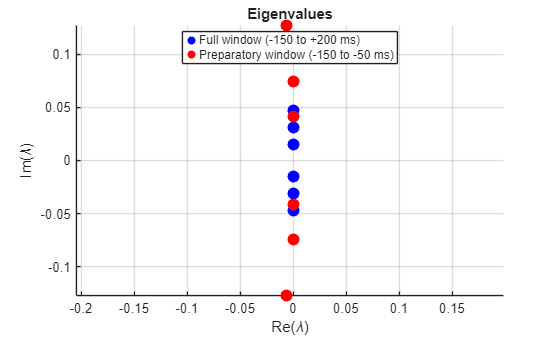


%% Part D + E plot
figure; 
hold on; 
grid on; 
axis equal;

% Full window (blue)
scatter(real(eigvals_AD), imag(eigvals_AD), 80, 'b', 'filled', ...
        'DisplayName', sprintf('Full window (%d to %+d ms)', epoch_AD));

% Preparatory window (red)
scatter(real(eigvals_E), imag(eigvals_E), 80, 'r', 'filled', ...
        'DisplayName', sprintf('Preparatory window (%d to %+d ms)', epoch_E));

xlabel('Re(\lambda)');
ylabel('Im(\lambda)');
title('Eigenvalues');
legend('Location', 'best');

The eigenvalues in the preparatory window have a wider distribution than the eigenvalues in the full window of movement. 

## Helper functions

function [M, eigvals, x] = fitDynamics(R, epoch_ms, sd_ms, bin_ms, n_pcs)
    nTrials = length(R);
    nUnits  = length(R(1).unit);
    t_start = epoch_ms(1);
    t_stop  = epoch_ms(2);
    nBins   = (t_stop - t_start) / bin_ms;

    % part A: smooth, trial-average, PCA
    kHalf  = ceil(3 * sd_ms);
    kTimes = -kHalf : kHalf;
    kernel = exp(-0.5 * (kTimes / sd_ms).^2);
    kernel = kernel / sum(kernel);

    psth = zeros(nUnits, nBins, nTrials);

    for tr = 1:nTrials
        t0 = R(tr).moveOnsetTime;
        for u = 1:nUnits
            spk    = R(tr).unit(u).spikeTimes;
            edges  = (t0 + t_start) : bin_ms : (t0 + t_stop);
            counts = histcounts(spk, edges);
            psth(u, :, tr) = conv(counts, kernel, 'same');
        end
    end

    meanPSTH = mean(psth, 3);   % nUnits x nBins

    % normalize matching PS5 Part 2A
    X = meanPSTH';              % nBins x nUnits
    column_range = max(X) - min(X);
    normalizer   = column_range + 5;
    X_norm       = X ./ normalizer;

    % PCA on normalized data
    [~, x, ~] = pca(X_norm, 'NumComponents', n_pcs);  % nBins x n_pcs

    % part B: estimate x_dot via finite differences
    x_dot = diff(x, 1, 1);
    x_mid = (x(1:end-1, :) + x(2:end, :)) / 2;

    % part C: fit x_dot = M * x via ordinary linear regression
    M = (x_mid \ x_dot)';

    % part D: eigenvalues
    eigvals = eig(M);
end